# **THIS IS NOT THE SWEEP TEST**

% Constant area
area_floor = 350;
height_aperture = 3;
width_aperture = 10;

% Parameters to sweep
thickness_floor = 0.25;
thickness_insulation = 0.25;

start_day = 1;
end_day = 180;
timespan = [start_day, end_day] * (24 * 60 * 60); % Convert date time ranges to seconds
max_timestep = 100000;

[T, Y, debug] = house_simulate(timespan, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T = T / (24 * 60 * 60);
debug(:, 1) = debug(:, 1) / (24 * 60 * 60);

% K to C
Y(:, 1:2) = Y(:, 1:2) - 273.15;
debug(:, 6:7) = debug(:, 6:7) - 273.15;

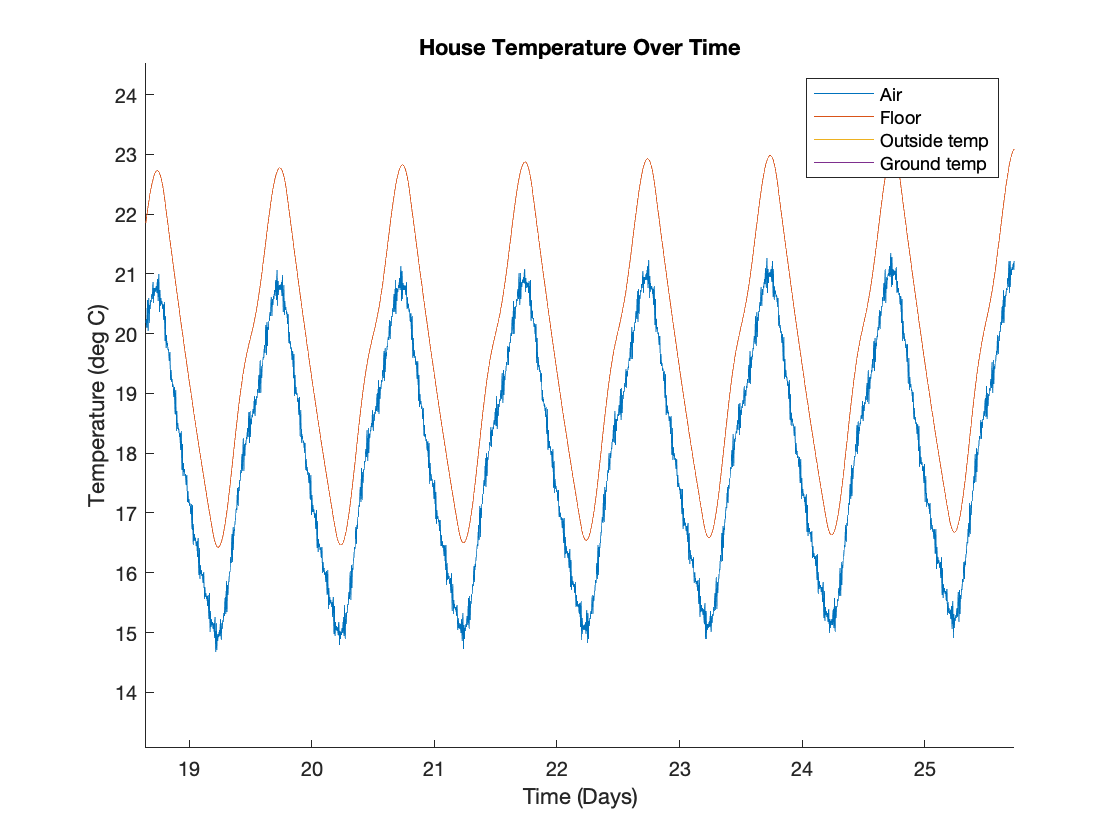

clf; hold on;
plot(T, Y(:, 1));
plot(T, Y(:, 2));
plot(debug(:, 1), debug(:,6))
plot(debug(:, 1), debug(:,7))

legend("Air", "Floor", "Outside temp", "Ground temp");
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("House Temperature Over Time");

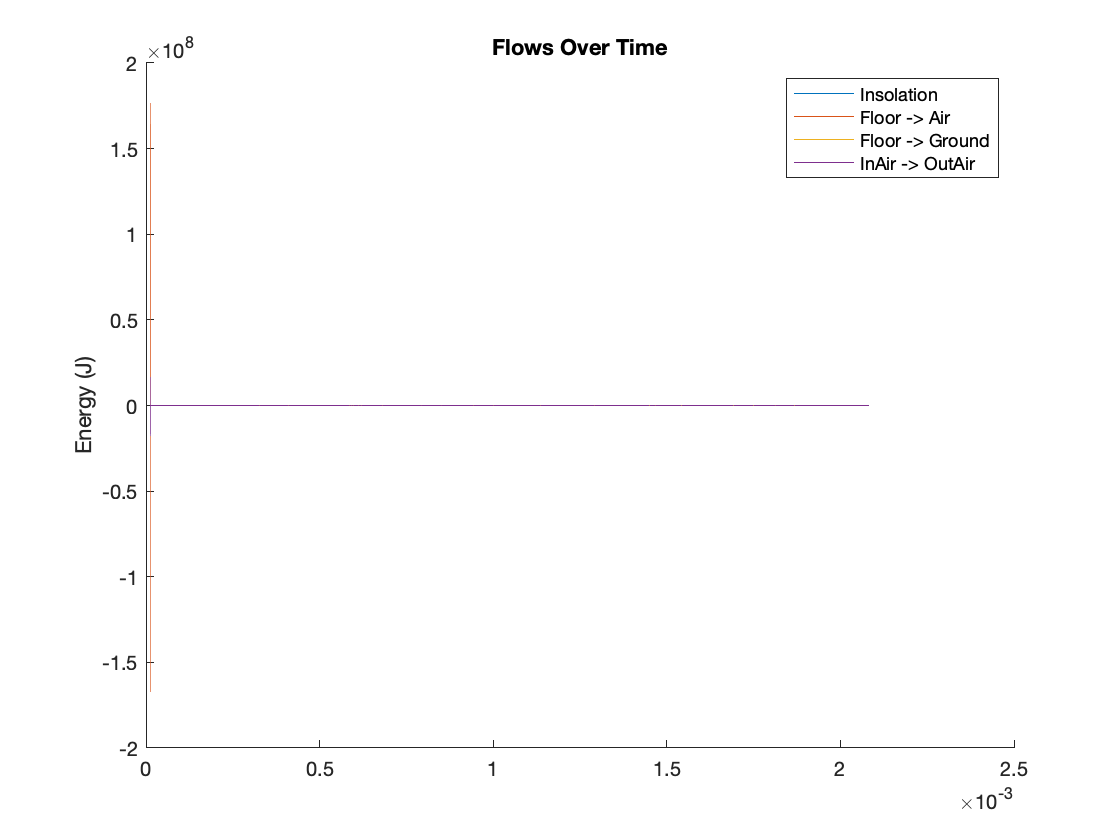

figure; clf; hold on;
plot(debug(2:end, 1) / (24 * 60 * 60), debug(2:end, 5));
plot(debug(2:end, 1) / (24 * 60 * 60), debug(2:end, 2));
plot(debug(2:end, 1) / (24 * 60 * 60), debug(2:end, 3));
plot(debug(2:end, 1) / (24 * 60 * 60), debug(2:end, 4));
ylabel("Energy (J)");

legend("Insolation", "Floor -> Air", "Floor -> Ground", "InAir -> OutAir");
title("Flows Over Time");